## Project 2: Calculating Values at Risk

### 1.

V = readtable('dat_intel.csv');
X = log(V.Close(2:end)) - log(V.Close(1:end-1));

### 2.

Plot the (sample) autocorrelation and partial autocorrelation functions of X for lags h = 0,...,50

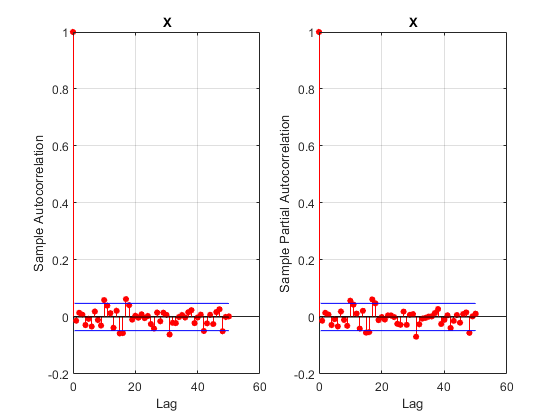

subplot(1,2,1)
autocorr(X,'NumLags',50)
title('X')
ylim([-.2, 1])

subplot(1,2,2)
parcorr(X,'NumLags',50)
title('X')
ylim([-.2, 1])

do a Ljung–Box test with h = 50 for X

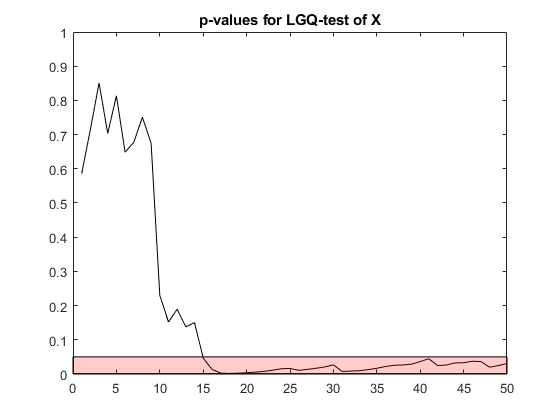

subplot(1,1,1)
resX = X - mean(X);
lags = 1:50;
[h, pValue, stat, cValue] = lbqtest(resX, 'lags', lags);

p = plot(lags, pValue, 'k');
tmp_x = [p.Parent.XLim(1) p.Parent.XLim(1) p.Parent.XLim(2) p.Parent.XLim(2)];
tmp_y = [p.Parent.YLim(1) .05 .05 p.Parent.YLim(1)];
patch(tmp_x, tmp_y, 'r', 'facealpha', .2)
ylim([0, 1])
title('p-values for LGQ-test of X')

Repeat these two steps with the squared returns. We start with the (sample) autocorrelation and partial autocorrelation functions of X^2 for lags h = 0,...,50

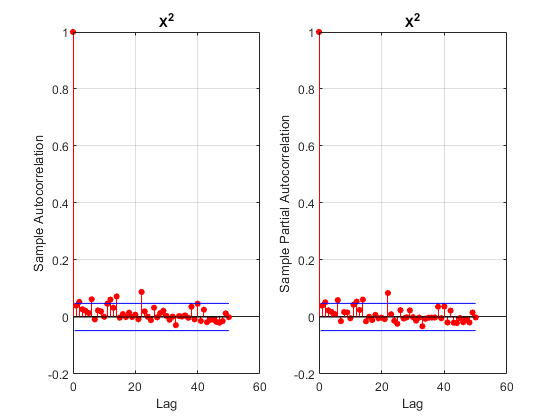

subplot(1,2,1)
autocorr(X.^2,'NumLags',50)
title('X^2')
ylim([-.2, 1])

subplot(1,2,2)
parcorr(X.^2,'NumLags',50)
title('X^2')
ylim([-.2, 1])

do a Ljung–Box test with h = 50 for X^2

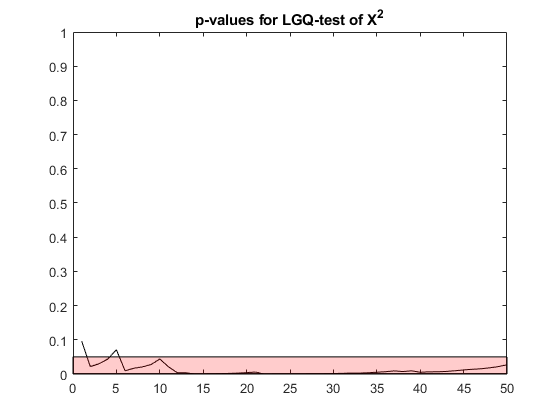

subplot(1,1,1)
resX = X.^2 - mean(X.^2);
lags = 1:50;
[h, pValue, stat, cValue] = lbqtest(resX, 'lags', lags);

p = plot(lags, pValue, 'k');
tmp_x = [p.Parent.XLim(1) p.Parent.XLim(1) p.Parent.XLim(2) p.Parent.XLim(2)];
tmp_y = [p.Parent.YLim(1) .05 .05 p.Parent.YLim(1)];
patch(tmp_x, tmp_y, 'r', 'facealpha', .2)
ylim([0, 1])
title('p-values for LGQ-test of X^2')

#### Discussion

Both $X$ and $X^2$(the squared returns) have outliers on the autocorrelation function plots. They are not very large, but significant enough to be above the 95% confidence interval plotted at a couple of lags, indicating that the series is not entirely white noise. The ljung-box test shows that for $X$, the first 15 lags seem to be white noise, but the remaining lags up to 50, is not. For $X^2$ it is only lag 5 (and 0?) that comes inside the 95% confidence interval for white noise.

### 3)

Now split the time series $X$ into a training set ($X_t$ , t = 2,...,1526) and a test set ($X_t$ , t = 1527, . . . , 1751).

trainX = X(2:1526);
testX = X(1527:1750);

For all values of p and q in the range 0, 1, . . . , 15 and such that p+q > 0 and p ≥ q, fit an ARMA(p, q) process with Gaussian noise to the square returns obtained from the training data and compute the BIC and the AICC (this will take a couple of minutes). Which models minimize the two information criteria? 

i=1;
for p = 1:15
    for q = 0:p
        mdl(i) = arima(p,0,q); 
        i = i + 1;
    end
end

https://se.mathworks.com/help/econ/aicbic.html

for i = 1:size(mdl,2)
    [EstMdl,~,logL(i)] = estimate(mdl(i),X,'Display','off');
    results = summarize(EstMdl);
    numParam(i) = results.NumEstimatedParameters;
end

[aic,bic,ic] = aicbic(logL,numParam,100)

Error using aicbic
Too many output arguments.